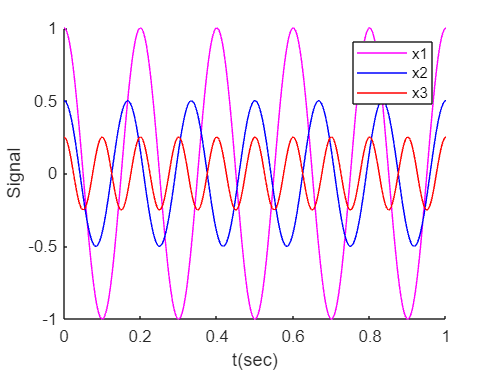

%Question 1:
%Part 1:
a = 1 + mod(114,3);
t = [0:0.001:1/a];
x1 = inline("a*cos(2*pi*5*a*t)",'a','t');
x2 = inline("(a/2)*cos(2*pi*6*a*t)",'a','t');
x3 = inline("(a/4)*cos(2*pi*10*a*t)",'a','t');
hold on
plot(t,x1(a,t),'m')
plot(t,x2(a,t),'b')
plot(t,x3(a,t),'r')
ylabel('Signal');
xlabel('t(sec)');
legend('x1','x2','x3')
hold off

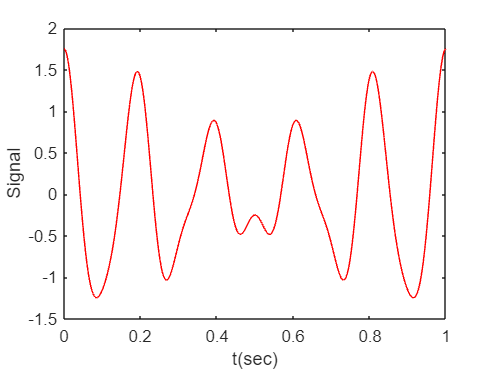



%Part 2:
s = x1(a,t)+x2(a,t)+x3(a,t);
plot(t,s,'r')
ylabel('Signal');
xlabel('t(sec)');

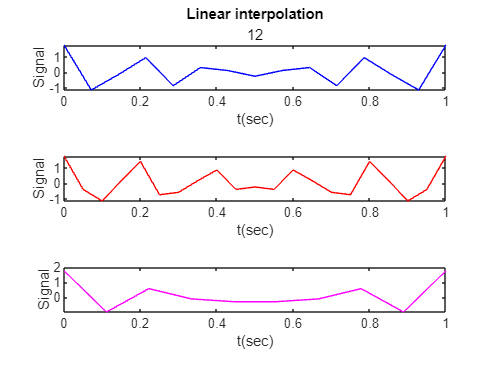


%Part 3:

%a
Fs = 14*a;
T = 1/Fs;
t =[0:T:a];
s = x1(a,t)+x2(a,t)+x3(a,t);
subplot(3,1,1)
stem(t,s,'b')
ylabel('Signal');
xlabel('t(sec)');
title('Discretization')

%b
Fs = 20*a;
T = 1/Fs;
t =[0:T:a];
s = x1(a,t)+x2(a,t)+x3(a,t);
subplot(3,1,2)
stem(t,s,'r')
ylabel('Signal');
xlabel('t(sec)');

%c
Fs = 9*a;
T = 1/Fs;
t =[0:T:a];
s = x1(a,t)+x2(a,t)+x3(a,t);
subplot(3,1,3)
stem(t,s,'m')
ylabel('Signal');
xlabel('t(sec)');


%Part 4:
%a
Fs = 14*a;
T = 1/Fs;
t =[0:T:a];
s = x1(a,t)+x2(a,t)+x3(a,t);
subplot(3,1,1)
plot(t,s,'b')
ylabel('Signal');
xlabel('t(sec)');
title('Linear interpolation','12')

%b
Fs = 20*a;
T = 1/Fs;
t =[0:T:a];
s = x1(a,t)+x2(a,t)+x3(a,t);
subplot(3,1,2)
plot(t,s,'r')
ylabel('Signal');
xlabel('t(sec)');

%c
Fs = 9*a;
T = 1/Fs;
t =[0:T:a];
s = x1(a,t)+x2(a,t)+x3(a,t);
subplot(3,1,3)
plot(t,s,'m')
ylabel('Signal');
xlabel('t(sec)');

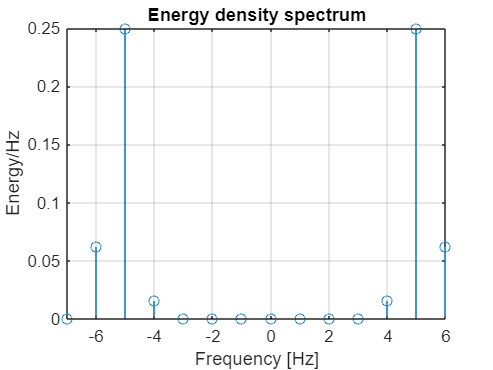


%Part 5:
%a
fs = 14*a;
T = 1/fs;
t =[0:T:a-T];
s = x1(a,t)+x2(a,t)+x3(a,t);
N=length(s);
y=fft(s,N); 
z=fftshift(y); 
f_vec=[0:1:N-1]*fs/N-fs/2; 
amplitude_spectra=abs(z)/fs; 
figure;stem(f_vec,abs(amplitude_spectra).^2);
xlabel('Frequency [Hz]')
ylabel('Energy/Hz')
title('Energy density spectrum')
grid on
set(gcf,'color','w');
axis tight

%calculate total energy
Eg=sum(s.^2)*T 

Eg = 0.6563

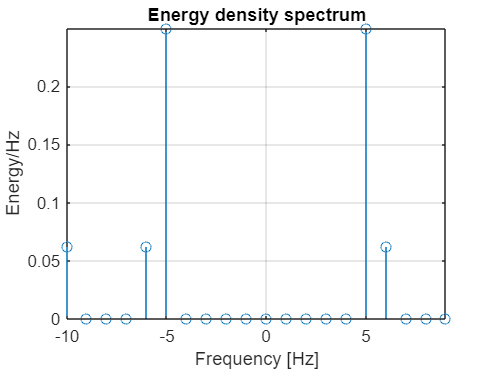


%b
fs = 20*a;
T = 1/fs;
t =[0:T:a-T];
s = x1(a,t)+x2(a,t)+x3(a,t);
N=length(s);
y=fft(s,N); 
z=fftshift(y); 
f_vec=[0:1:N-1]*fs/N-fs/2; 
amplitude_spectra=abs(z)/fs; 
figure;stem(f_vec,abs(amplitude_spectra).^2);
xlabel('Frequency [Hz]')
ylabel('Energy/Hz')
title('Energy density spectrum')
grid on
set(gcf,'color','w');
axis tight

Eg=sum(s.^2)*T 

Eg = 0.6875

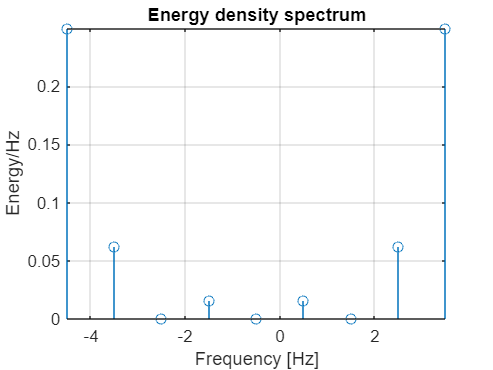


%c
fs = 9*a;
T = 1/fs;
t =[0:T:a-T];
s = x1(a,t)+x2(a,t)+x3(a,t);
N=length(s);
y=fft(s,N); 
z=fftshift(y); 
f_vec=[0:1:N-1]*fs/N-fs/2; 
amplitude_spectra=abs(z)/fs; 
figure;stem(f_vec,abs(amplitude_spectra).^2);
xlabel('Frequency [Hz]')
ylabel('Energy/Hz')
title('Energy density spectrum')
grid on
set(gcf,'color','w');
axis tight

Eg=sum(s.^2)*T 

Eg = 0.6562

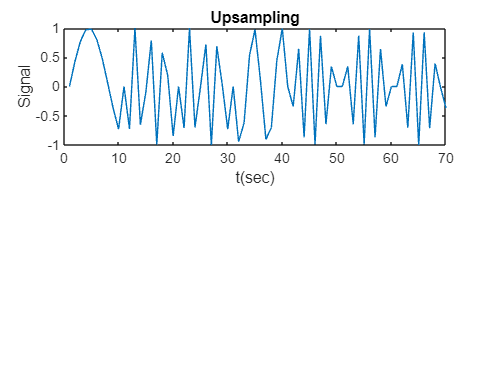


%Question 2:
% Upsampling
Fs = 10;
t = linspace(0,1,Fs);
Do = sin(2*pi*261.63*t);
Re = sin(2*pi*293.66*t);
Mi = sin(2*pi*329.63*t);
Fa = sin(2*pi*349.23*t);
So = sin(2*pi*392.00*t);
La = sin(2*pi*220.00*t);
Ti = sin(2*pi*246.94*t);
z = [Do,Re,Mi,Fa,So,La,Ti];
figure;
subplot(2,1,1)
plot(z)
ylabel('Signal');
xlabel('t(sec)');
title('Upsampling')


y1 = upsample(z,5);

'upsample' requires one of the following:
  Control System Toolbox
  Signal Processing Toolbox

subplot(2,1,2)
plot(y1)
ylabel('Signal');
xlabel('t(sec)');

% Downsampling
Fs = 80;
t = linspace(0,1,Fs);
Do = sin(2*pi*261.63*t);
Re = sin(2*pi*293.66*t);
Mi = sin(2*pi*329.63*t);
Fa = sin(2*pi*349.23*t);
So = sin(2*pi*392.00*t);
La = sin(2*pi*220.00*t);
Ti = sin(2*pi*246.94*t);
z = [Do,Re,Mi,Fa,So,La,Ti];
figure;
subplot(2,1,1)
plot(z);
ylabel('Signal');
xlabel('t(sec)');
title('Downsampling')

y2 = downsample(z,3);
subplot(2,1,2)
plot(y2);
ylabel('Signal');
xlabel('t(sec)');

% For audio 
Fs = 44100;
t = linspace(0,5,20000);
Do = sin(2*pi*261.63*t);
Re = sin(2*pi*293.66*t);
Mi = sin(2*pi*329.63*t);
Fa = sin(2*pi*349.23*t);
So = sin(2*pi*392.00*t);
La = sin(2*pi*220.00*t);
Ti = sin(2*pi*246.94*t);
z = [Do,Re,Mi,Fa,So,La,Ti];
audiowrite('Tone.wav',z,Fs);
%sound(z,44100);
%sound(z,22050);
%sound(z,10250);



%Question 3:
[s,Fs] =audioread('Track001.wav');

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);

y1 = downsample(s,2);
y2 = upsample(s,3);
%sound(y1,Fs)
%sound(y2,Fs)